% SHAPC-Mean and SHAPC-Var Comparison
algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", ...
     "der", "icarl", "dsal", "tagfex", "xder"];
dataset = 'cifar100';

if dataset == "cifar100"
    num_sessions = 10;
    cls_per_task = 10;
else
    num_sessions = 5;
    cls_per_task = 2;
end

if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end
num_algs = length(algs);

file_path = sprintf("%s_all_inclass_shapcs_new.mat", dataset);
if isfile(file_path)
    all_inclass_shapcs = load(file_path).all_inclass_shapcs;
else
    all_inclass_shapcs = zeros(((num_sessions-1)*cls_per_task), num_algs+1);
end

for j=1:length(algs)
    alg = algs(j);
    % Load SHAPC values (First and Last 1000)
    save_path = sprintf("%s/%s/shapc_vals_inclass_new.mat", alg, dataset);
    if isfile(save_path)
        inclass_struct = load(save_path);
    
        for i=1:((num_sessions-1)*cls_per_task)
            cls = i - 1;
    
            cls_str = sprintf("cls%d", cls);
            shapc_struct = inclass_struct.(cls_str);
           
            % Load SHAPC values all
            shapc_avgs = [];
            pair_str = 'sc' + string(floor(cls/cls_per_task)) + string(num_sessions-1);
            shapcs = [];
            sample_list = string(fieldnames(shapc_struct.(pair_str)));
            for k=1:length(fieldnames(shapc_struct.(pair_str)))
                sample_str = sample_list(k);%'sample' + string(k-1);
                shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
            end
            shapc_avgs = [shapc_avgs; mean(shapcs)];
            
            % Note the shapc is represented as percentage
            %disp("From averaging all tasks together:")
            shapc_mean_perc = mean(shapc_avgs);
            shapc_mean = mean(shapc_avgs) / 100;
                        
            if ~exist('inclass_shapcs','var') || length(inclass_shapcs) ~= (num_sessions-1)*cls_per_task
                inclass_shapcs = zeros(((num_sessions-1)*cls_per_task),2);
            end
            
            inclass_shapcs(cls+1,1) = cls;
            inclass_shapcs(cls+1,2) = shapc_mean_perc;
        end
        all_inclass_shapcs(:, find(algs==alg)+1) = inclass_shapcs(:,2);
    end
    save(file_path, "all_inclass_shapcs")
end

% Display All Results
fprintf('Inclass SHAPC-Mean Percentages:\n');

Inclass SHAPC-Mean Percentages:


disp(inclass_shapcs);

         0   31.1141
    1.0000   27.8029
    2.0000   27.2978
    3.0000   25.0521
    4.0000   26.1444
    5.0000   27.7306
    6.0000   31.1050
    7.0000   28.1020
    8.0000   28.5603
    9.0000   28.6253
   10.0000   24.5506
   11.0000   30.5870
   12.0000   25.3682
   13.0000   31.1017
   14.0000   27.1429
   15.0000   28.8223
   16.0000   29.1745
   17.0000   31.3876
   18.0000   28.0600
   19.0000   28.0948
   20.0000   34.7302
   21.0000   33.1394
   22.0000   29.6603
   23.0000   34.8072
   24.0000   32.6246
   25.0000   28.8410
   26.0000   29.5205
   27.0000   24.4474
   28.0000   31.9324
   29.0000   28.4173
   30.0000   28.7763
   31.0000   30.8546
   32.0000   26.6270
   33.0000   29.5431
   34.0000   30.1040
   35.0000   30.7777
   36.0000   32.2797
   37.0000   34.2931
   38.0000   27.9199
   39.0000   36.5487
   40.0000   31.6272
   41.0000   36.7490
   42.0000   33.7059
   43.0000   38.7608
   44.0000   30.1969
   45.0000   31.2707
   46.0000   38.1836
   47.0000   


fprintf('Std Dev:\n');

Std Dev:


disp(std(inclass_shapcs(:,2)))

    7.2630




fprintf('Avg:\n');

Avg:


disp(mean(inclass_shapcs(:,2)))

   35.6150



create_table = true;
if create_table
    if ~exist('inclass_shapcs','var')
        all_inclass_shapcs = load(file_path).all_inclass_shapcs;
    end

    % Create a table for better visualization of results
    all_inclass_shapcs(:, 1) = (1:(num_sessions-1)*cls_per_task)-1;
    resultsTable = array2table(all_inclass_shapcs, 'VariableNames', ['Class' algs]);
    disp(resultsTable);

    all_std_devs = [NaN std(all_inclass_shapcs(:, 2:end))]
    %fprintf('Std Devs:\n');
    %disp(all_std_devs);

    all_avgs = [NaN mean(all_inclass_shapcs(:, 2:end))];
    fprintf('Averages:\n');
    
    disp(all_avgs);
end

    Class    iTAML     RPSnet    foster     memo      der      icarl      dsal     tagfex     xder 
    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______

      0      23.369     27.87    27.566    25.689    34.824     25.71    40.741    29.749    31.114
      1      26.426    22.422    25.767    24.619    31.907    22.395    36.694    28.053    27.803
      2      24.373    26.139    23.934    23.354    25.832    23.564    35.969    26.372    27.298
      3      22.781    22.992    23.868    21.972    25.382    23.571    34.498    25.462    25.052
      4      22.883    20.698    25.329    22.281    25.291

all_std_devs =        NaN    3.1461    8.2604    3.4549    5.0151    9.0282    4.5198    9.6471    8.5033    7.2630


Averages:


       NaN   27.4833   30.6125   28.7846   30.9923   41.6397   27.3165   43.4984   40.7168   35.6150




% Cls 7 has the highest SHAPCs for all algs
% Except for foster -> Cls 8

% Cls 1 has the lowest SHAPCs for all algs
% Except for RPSnet -> Cls 4

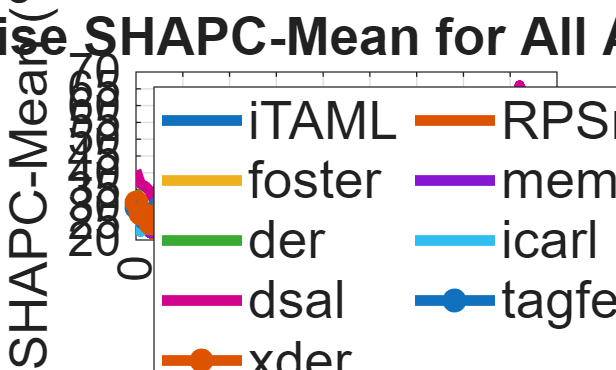

% Plot inclass shapcs

plot((all_inclass_shapcs(:, 1)), ...
    (all_inclass_shapcs(:, 2:end)), ...
    'LineWidth', 4, 'MarkerSize', 5)
linestyles = ["-", "-", "-", "-", "-", "-", "-", "-o", "-o"];
linestyleorder(linestyles)
legend(algs,"Location", "northwest")
ax = gca;
ax.FontSize = 14;
title('Classwise SHAPC-Mean for All Algorithms');
xlabel('Class');
ylabel('SHAPC-Mean (%)');

grid on;